clc; clear; close all;

# TAKEOFF POWER as a function of MASS

## Parameters


syms x_a x_g T_mean mu_p P V_LOF C_Lmax P_eng


Parameters

% runway
x_tot = 85;         % length - 21 m
h = 50 * 0.3048;    % obtacle height (feet to meters conversion)

% physical constants
g = 9.81;           % gravity
rho_0 = 1.225;      % air density at ground

% Aircraft characteristics
% W_to = 1500 * g;    % take off weight
% S = 20;             % [m^2] wing surface

AR = 8;             % between 7 and 9
mu = 0.02;          % ground friction coeff at takeoff on concrete
sweep_angle = 0;    % for speed range
C_Lmax_sweep = 2.5; % before sweep

% assumptions
C_D0 = 0.02;        % drag coeff (assumption)
e = 0.75;
%lambda = 40;       % bypass ratio for turbopropeller

% engine
prop_efficiency = 0.5; % at take-off

% Propeller
% K_p = 0.321;        % for SI units
% P_to = 0;           % [W] maximum engine power
% sigma = 0;          % [-] density ratio
% N_e = 0;            % ?????
% D_p = 0;            % [m] propeller diameter

## Mass graph

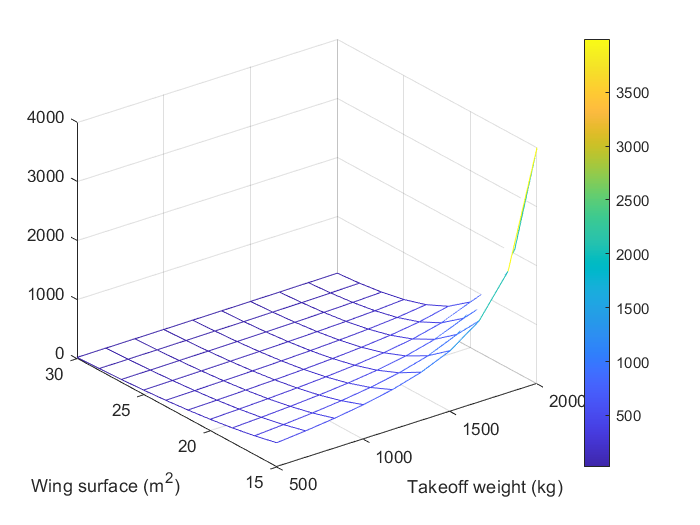

masses = linspace(500, 2000, 10) * g;
surfaces = linspace(15,30,10);
P_graph = zeros(length(masses), length(surfaces));

for i = 1:length(masses)
    for j = 1:length(surfaces)
        
        W_to = masses(i);
        S = surfaces(j);
        
        runway_length = x_tot == x_a + x_g;
        air_distance_cond = x_a > 0;
        air_distance = x_a == V_LOF^2 / (g*sqrt(2)) + h / (0.9 * T_mean / W_to - 0.3 / sqrt(AR));
        ground_distance_cond = x_g > 0;
        ground_distance = x_g == V_LOF^2 / (2 * g) / (T_mean / W_to - mu_p);
        friction_coeff = mu_p == mu + 0.72 * C_D0 / C_Lmax;
        power = P == T_mean * V_LOF / sqrt(2);
        power_eng = P_eng == P / prop_efficiency;
        liftoff_speed = V_LOF == 1.1 * sqrt(2 * W_to / (rho_0 * S * C_Lmax));
        lift_coeff = C_Lmax == C_Lmax_sweep * cos(sweep_angle);
        power_cond = P_eng / 746 < 50000;
        
        sol = solve([runway_length, ...
             air_distance, ...
             air_distance_cond, ...
             ground_distance, ...
             ground_distance_cond, ...
             friction_coeff, ...
             power, ...
             liftoff_speed, ...
             lift_coeff, ...
             power_eng, ...
             power_cond], ...
             [x_a, x_g, T_mean, mu_p, P, V_LOF, C_Lmax, P_eng]);
        
        P_graph(i, j) = vpa(sol.P) / 746;
    end
end

mesh(flip(masses) / g, flip(surfaces), P_graph); hold on;
xlabel('Takeoff weight (kg)');
ylabel('Wing surface (m^2)');
colorbar;